# Numerical Differentitation

La diferenciación númerica aproxima el valor de una de la derivada de una función utilizando una serie de puntos, la cual puede ser dada o se pueden obtener de la misma función pasada como parametro.

    En este caso usaremos la segunda opción, es decir, definiremos una función y=f(x)

%f = @(x) cosh(x);   % in-line function declaration

El método utilizado para aproximar será el de las series de Taylor. Esto tiene como consecuencia que existan dos fuentes de error inevitables:

- redondeo de la maquina (debido a la precisión limitada)

- error de truncamiento de las series de taylor (no planeamos resolverlas hasta converger, sino truncarlas en cierto punto)

## Taylor series

Por definición, la aproximación con una serie de taylor par auna función $$f(x)$$ alderedor del punto $$a$$ es:


$$f\left(x\right)\;\approx f\left(a\right)+\frac{f^{\prime } \left(a\right)}{1!}\left(x-a\right)+\frac{f^{\prime \prime } \left(a\right)}{2!}{\left(x-a\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(a\right)}{n!}{\left(x-a\right)}^n$$


Ahora, si aproximamos en funcion de $x+h$ alrededor de un punto $x$


$$f\left(x+h\right)\approx f\left(x\right)+\frac{f^{\prime } \left(x\right)}{1!}\left(h\right)+\frac{f^{\prime \prime } \left(x\right)}{2!}{\left(h\right)}^2 +\ldotp \ldotp \ldotp ,=\sum_{n=0}^{\infty } \frac{f^{\left(n\right)} \left(x\right)}{n!}{\left(h\right)}^n$$


## First derivative

Resolviendo varias funciones de taylor, podemos despejar la primera derivada de x de la ecuacion resultante al substraer de la serie de f(x+h) alrededor de x de la serie de f(x-h) alrededor de x.


$$f\left(x+h\right)-f\left(x-h\right)\approx 2\left\lbrack {\textrm{hf}}^{\prime } \left(x\right)+\frac{h^3 }{3!}f^{\prime \prime \prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right\rbrack$$


despejando para ${f}'(x)$


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{1}{h}\left(\frac{h^3 }{3!}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)+\ldotp \ldotp \ldotp ,\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}-\frac{h^2 }{6}{{f^{\prime } }^{\prime } }^{\prime } \left(x\right)-\ldotp \ldotp \ldotp$$


por lo que si fijamos x y variamos h para identificar la precision de la aproximación, podemos asumir que el error de truncamiento se comporta como $h^2$. Es decir.


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$

$$$+ \mathcal{O}(h^2)$$$


Ya que *h *es la mayoria de las veces menor a 1, a mayor grado de exponente en *h* , mejor es la aproximación.

En el caso de querer mejorar la precisión, deberiamos calcular más series de Taylor como funciones de $x\pm (n)h$ y cancelaras entre sí.

## Generalization

Usando el método anteriormente descrito, llegamos a tres formas distintas, las aproximaciones centradas, hacia adelante y hacia atrás. Analizaremos la primera y la segunda derivada de las funciones $f(x) = e^{-x}$  y $g(x) = \ln{x}$

format long
syms g(x) f(x);
f(x)=exp(-x) 

$$f(x) = {\mathrm{e}}^{-x}$$

func1 = @(x)  exp(-x);
%f(x)=log(x)
%func2 = @(x) log(x);

c=0.6;
i = 1:50;
arr = @(x) double(power(c,x));

hs = arr(i)

hs =    0.600000000000000   0.360000000000000   0.216000000000000   0.129600000000000   0.077760000000000   0.046656000000000   0.027993600000000   0.016796160000000   0.010077696000000   0.006046617600000   0.003627970560000   0.002176782336000   0.001306069401600   0.000783641640960   0.000470184984576   0.000282110990746   0.000169266594447   0.000101559956668   0.000060935974001   0.000036561584401   0.000021936950640   0.000013162170384   0.000007897302231   0.000004738381338   0.000002843028803   0.000001705817282   0.000001023490369   0.000000614094221   0.000000368456533   0.000000221073920   0.000000132644352   0.000000079586611   0.000000047751967   0.000000028651180   0.000000017190708   0.000000010314425   0.000000006188655   0.000000003713193   0.000000002227916   0.000000001336749   0.000000000802050   0.000000000481230   0.000000000288738   0.000000000173243   0.000000000103946   0.000000000062367   0.000000000037420   0.000000000022452   0.000000000013471   0.0000000000

x=2

x =      2


## Central Finite Difference

Las aproximaciones pueden realizarse de forma "centralizada", este nombre proviene de la necesidad de calcular los puntos $f\left(x+h\right)$ y $f\left(x-h\right)$ para una x que se encuentra en el centro de estos dos. 

    Usaremos las dos siguientes formulas para aproximar la primera y segunda derivada de las funciones.


$$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x-h\right)}{2h}$$

$$$+ \mathcal{O}(h^2)$$$



$$f^{\prime \prime } \left(x\right)\approx \frac{f\left(x+h\right)-2f\left(x\right)+f\left(x-h\right)}{h^2 }$$

$$$+ \mathcal{O}(h^2)$$$


%calcular valor real
df      = diff(f)
df_x    = double(df(x))

$$df(x) = -{\mathrm{e}}^{-x}$$

d2f     = diff(f,2)

df_x =     -329/2431  


df2_x   = double(d2f(x))

$$d2f(x) = {\mathrm{e}}^{-x}$$

df2_x =      329/2431  


error = zeros([2,length(hs)])


error =        0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0       
       0              0              0              0              0              0              0              0              0              0              0              0              0              0              0              0        

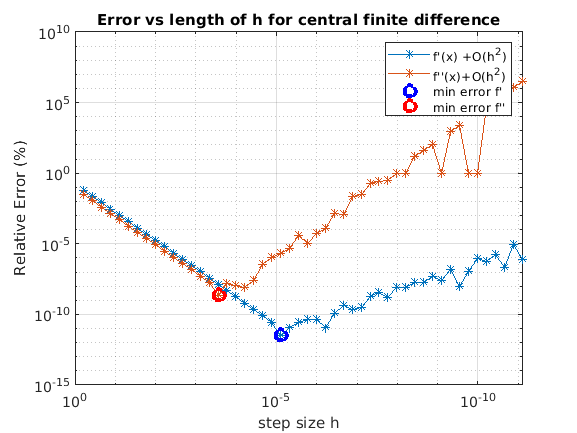

j=1;
for h = hs
    ap1 = firstCenteredDerivative(func1,x,h);
    ap2 = secondCenteredDerivative(func1,x,h);
    error(1,j)=abs(ap1/df_x -1);
    error(2,j)=abs(ap2/df2_x -1);
    j = j+1;
end


figure;
loglog(hs,error,'-*')
hold on
%semilogx(hs,error)
%semilogx(hs,error(2,:))
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o",'MarkerSize',8,'LineWidth',3)
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',8,'LineWidth',3)
set(gca,'XDir','reverse')
xlabel("step size h")
ylabel("Relative Error (%)")



% dft = diff(f,4)
% m = double(dft(x))
% m2 = power((3*eps)/m,1/4)
% ym2 = abs(secondCenteredDerivative(func1,x,m2)/df2_x -1)
% loglog(m2,ym2,"r *")
% 
% 
% dft = diff(f,3)
% m = abs(double(dft(x)))
% m2 = power((3*eps)/m,1/3)
% ym2 = abs(firstCenteredDerivative(func1,x,m2)/df_x -1)
grid
% loglog(m2,ym2,"b *")
title("Error vs length of h for central finite difference")
legend("f'(x) +O(h^2)","f''(x)+O(h^2)","min error f'","min error f''" )
hold off


## Forward Finite Difference

Similarmente a como despejamos las derivadas primera y segunda de un sistema de ecuaciones de series de Taylor, podemos despejarlas de manera que sólo usemos puntos adelante de $x$, es decir, puntos de la forma $x+\left(n\right)h$ para $n\ge 0$.

### First forward finite difference

$f^{\prime } \left(x\right)\approx \frac{f\left(x+h\right)-f\left(x\right)}{h}+$$$ \mathcal{O}(h)$$                                                (a)

$f^{\prime } \left(x\right)\approx \frac{-\frac{1}{2}\;f\left(x+2h\right)+2f\left(x+h\right)-\frac{3}{2}f\left(x\right)}{h}+$$$ \mathcal{O}(h^2)$$                (b)

La ecuación (a) y (b) aproximan la primera derivada de $f\left(x\right)$, sin embargo (b) lo hace con mayor precisión, pues el error de truncamiento es de orden 2, y como $h\le 1\;$, el error se minimiza.

error = zeros([2,length(hs)])

j=1;

error =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for h = hs
    ap1 = forwardFiniteDifference(func1,x,h,1,1);
    ap2 = forwardFiniteDifference(func1,x,h,1,2);
    error(1,j)=abs(ap1/df_x -1);
    error(2,j)=abs(ap2/df_x -1);
    j = j+1;
end

figure;
loglog(hs,error,"-*")
hold on
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
hold off

segunda derivada

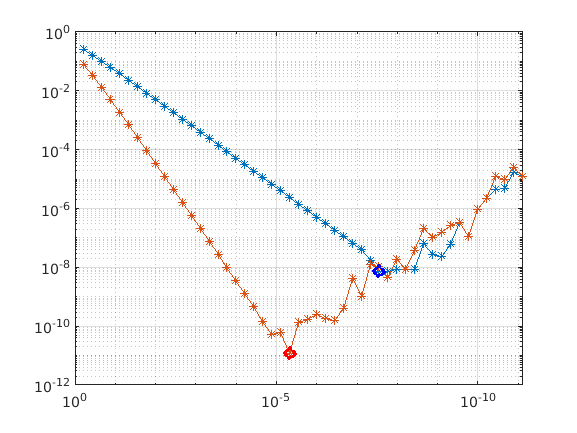

error = zeros([2,length(hs)]);


j=1;
for h = hs
    ap1 = forwardFiniteDifference(func1,x,h,2,1);
    ap2 = forwardFiniteDifference(func1,x,h,2,2);
    error(1,j)=abs(ap1/df2_x -1);
    error(2,j)=abs(ap2/df2_x -1);
    j = j+1;
end

%error

figure;
loglog(hs,error,"-*")
hold on
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
hold off

backwardFiniteDifference

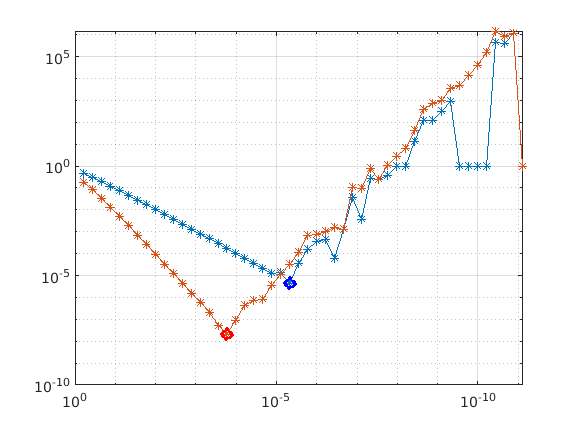

%error = zeros([2,length(hs)])


j=1;
for h = hs
    ap1 = backwardFiniteDifference(func1,x,h,1,1);
    ap2 = backwardFiniteDifference(func1,x,h,1,2);
    error(1,j)=abs(ap1/df_x -1);
    error(2,j)=abs(ap2/df_x -1);
    j = j+1;
end

figure;
loglog(hs,error,"-*")
hold on
[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
hold off

a

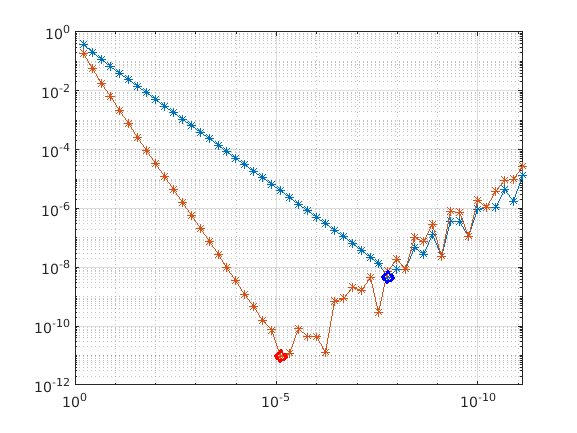

error = zeros([2,length(hs)]);

j=1;

for h = hs
    ap1 = backwardFiniteDifference(func1,x,h,2,1);
    ap2 = backwardFiniteDifference(func1,x,h,2,2);
    error(1,j)=abs(ap1/df2_x -1);
    error(2,j)=abs(ap2/df2_x -1);
    j = j+1;
end

error

figure;
loglog(hs,error,"-*")
hold on

error = 	1.0e+06 *

   0.000000877442561   0.000000448876401   0.000000245935296   0.000000139967193   0.000000081407961   0.000000047951593   0.000000028456262   0.000000016961916   0.000000010137196   0.000000006068001   0.000000003635660   0.000000002179549   0.000000001307065   0.000000000784000   0.000000000470313   0.000000000282158   0.000000000169296   0.000000000101554   0.000000000060929   0.000000000036695   0.000000000021796   0.000000000014314   0.000000000005501   0.000000000004364   0.000000000037248   0.000000000010679   0.000000000051971   0.000000000117232   0.000000001567465   0.000000002910274   0.000000014100347   0.000000003739168   0.000000079289428   0.000000000657937   0.000000387975087   0.000002927743177   0.000001000000000   0.000028749123102   0.000042318226530   0.000228545702944   0.000001000000000   0.001770185979505   0.002458980527091   0.000001000000000   0.018982331227550   0.000001000000000   0.146461889101468   0.406834803059632   1.130100452943422

[minV,idx] = min(error(1,:));
loglog(hs(idx),error(1,idx),"b o",'MarkerSize',7,'LineWidth',3)
[minV,idx] = min(error(2,:));
loglog(hs(idx),error(2,idx),"r o",'MarkerSize',7,'LineWidth',3)
set(gca,'XDir','reverse')
grid
hold off

## m-th derivative with precision n 

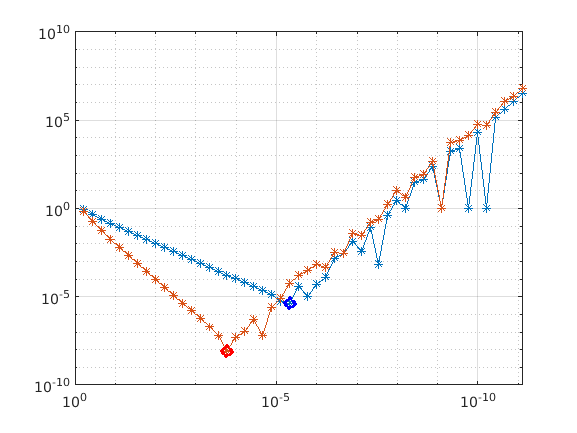

n=4;m=2;
n_coefs=2*floor((m+1)/2)-1+n; p=(n_coefs-1)/2;
% Solve system A*w = b

A=power(-p:p,(0:2*p)'); b=zeros(2*p+1,1); b(m+1)=factorial(m); coefs=A\b %inv(A)*b

% Round elements near values close to machine-epsilon to zero
coefs = coefs.*not(abs(coefs)<2000*eps);
format rational;
coefs

coefs =   -0.083333333333333
   1.333333333333333
  -2.500000000000000
   1.333333333333333
  -0.083333333333333


coefs =       -1/12    
       4/3     
      -5/2     
       4/3     
      -1/12    
